# Model Lockdown Calibration

Taking advantage of [**snw_calibrate_lockdown_c**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/calibrate/snw_calibrate_lockdown_c.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function finds the proportional discount to current utility in one period to account for aggregate reducntions in consumption during lockdown. 

## Lock Down Impact on Consumption

"To calibrate the drop in marginal utility, we estimate that 10.9 percent of the goods that make up the consumer price index become highly undesirable, or simply unavailable, during the pandemic: food away from home, public transportation including airlines, and motor fuel. As we use a coefficient of risk aversion equal to one, we simply multiply utility from consumption during the period of the epidemic by a factor of 0.891"

There is one MIT shock period in which households face a one-period change in the current utility of consumption due to lock down. Solve the model and evaluate the effects on aggregate consumption (during the MIT shock period) with different proportional adjustments on consumption given differing intertemperal preference assumptions.

## Graphical Illustraiton for Gamma=2 (docdense) and Gamma=1 (dense)

Solved Gamma=2 with docdense (81x5 shocks), and Gamma=1 with dense (7x5) shocks. Did not have time to resolve Gamma=1 with docdense.

Solved for gamma equals to 2, results visualized below. 

% Percentage C drop desired
fl_c_drop_percent = 0.109;

First, grid of proportional one period current utility shifts:

% Grid of proportional one period current utility shifts.
[fl_invbtlock_min, fl_invbtlock_max, it_invbtlock_points] = deal(0, 1, 20);
st_grid_type = 'grid_powerspace';
mp_grid_control = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_grid_control('grid_powerspace_power') = 1.5;
[ar_fl_invbtlock] = ff_saveborr_grid(...
    fl_invbtlock_min, fl_invbtlock_max, it_invbtlock_points, ...
    st_grid_type, mp_grid_control);
ar_fl_invbtlock = 1-ar_fl_invbtlock;
% display
% disp(ar_fl_invbtlock);

Second, stored aggregate consumption values from docdense:

% From gamma=2 docdense
ar_fl_cons_mean_betaedu_innerwgt_gamma2_docdense = [...
    1.0466,1.0434,1.0374,1.0293,...
    1.0191,1.0067,0.99214,0.97543,...
    0.95642,0.93482,0.90995,0.88078,...
    0.847,0.80734,0.76126,0.70507,...
    0.635, 0.54343, 0.40755, 0.00013065];
% From gamma=1 dense
ar_fl_cons_mean_betaedu_innerwgt_gamma1_dense = [...
    1.2517,1.2467,1.237,1.2228,...
    1.2031,1.1783,1.1489,1.1147,...
    1.0754,1.0311,0.98169,0.92291,...
    0.85528,0.77933,0.69408,0.5964,...
    0.47976, 0.34416, 0.18672, 0.00013642];

Third, polynomial fit (4th order) between the 3rd and 14th point:

% Generate polynomial fit coefficients
ft_polynomial_gamma2_docdense = polyfit(ar_fl_invbtlock(3:13), ...
    ar_fl_cons_mean_betaedu_innerwgt_gamma2_docdense(3:13), 4);
ft_polynomial_gamma1_dense = polyfit(ar_fl_invbtlock(3:13), ...
    ar_fl_cons_mean_betaedu_innerwgt_gamma1_dense(3:13), 4);
% Evaluate polynomial fits
ar_fl_cons_mean_polyfit_gamma2_docdense = ...
    polyval(ft_polynomial_gamma2_docdense, ar_fl_invbtlock)';
ar_fl_cons_mean_polyfit_gamma1_dense = ...
    polyval(ft_polynomial_gamma1_dense, ar_fl_invbtlock)';

Fourth, find which proportional current utility change in 2020 matches a 10.9 percent drop in aggregate consumption in 2020:

% Identify the exact point along polynomial where c drops by 10.9 percent
% Gamma = 2, docdense
ar_fl_invbtlock_interpgrid = linspace(0.50, 0.95, 100000);
ar_fit_reduce_grid = 1 - ...
    polyval(ft_polynomial_gamma2_docdense, ar_fl_invbtlock_interpgrid)...
    ./ar_fl_cons_mean_polyfit_gamma2_docdense(1);
[fl_mingap, it_minidx] = min(abs(ar_fit_reduce_grid-fl_c_drop_percent));
fl_fit_best_reduce = ar_fl_invbtlock_interpgrid(it_minidx);
fl_lockdown_u_prop_reduction_gamma2_docdense = (1-fl_fit_best_reduce)*100;
st_reduction_gamma2_docdense = ['current util in 2020 multiply by ', ...
    num2str(fl_fit_best_reduce), ...
    ' for 10.9 percent drop in C'];
% Gamma = 1, dense
ar_fl_invbtlock_interpgrid = linspace(0.50, 0.95, 100000);
ar_fit_reduce_grid = 1 - ...
    polyval(ft_polynomial_gamma1_dense, ar_fl_invbtlock_interpgrid)...
    ./ar_fl_cons_mean_polyfit_gamma1_dense(1);
[fl_mingap, it_minidx] = min(abs(ar_fit_reduce_grid-fl_c_drop_percent));
fl_fit_best_reduce = ar_fl_invbtlock_interpgrid(it_minidx);
fl_lockdown_u_prop_reduction_gamma1_dense = (1-fl_fit_best_reduce)*100;
st_reduction_gamma1_dense = ['current util in 2020 multiply by ', ...
    num2str(fl_fit_best_reduce), ...
    ' for 10.9 percent drop in C'];

Third, graphical illustration:

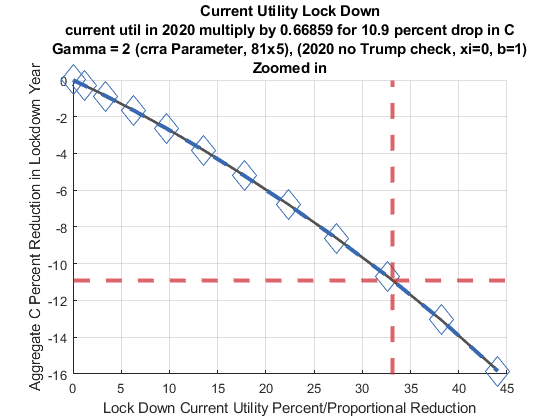

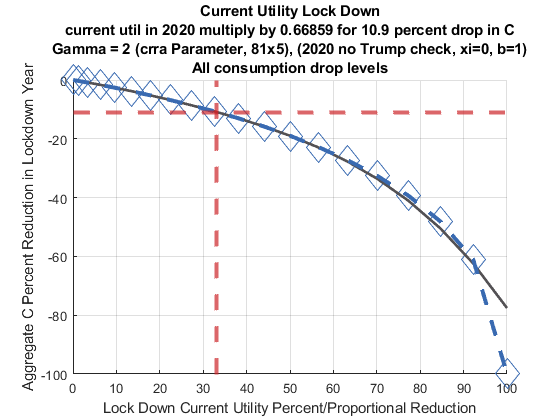

for it_graph_type=1:2
    if (it_graph_type == 1)
        st_title_add = 'Zoomed in';
    else
        st_title_add = 'All consumption drop levels';
    end
    
    for it_gamma=2:1:2
        figure();    
        hold on;
        
        if (it_graph_type == 1 && it_gamma == 1)
            ar_fl_cons_mean_betaedu_innerwgt_select = ...
                ar_fl_cons_mean_betaedu_innerwgt_gamma1_dense(1:12);
            ar_fl_cons_mean_polyfit_select = ...
                ar_fl_cons_mean_polyfit_gamma1_dense(1:12);
            st_gamma = 'Gamma = 1 (crra Parameter, 7x5), (2020 no Trump check, xi=0, b=1)';
            fl_lockdown_u_prop_reduction = fl_lockdown_u_prop_reduction_gamma1_dense;
            st_reduction = st_reduction_gamma1_dense;
        elseif (it_graph_type == 1 && it_gamma == 2)
            ar_fl_cons_mean_betaedu_innerwgt_select = ...
                ar_fl_cons_mean_betaedu_innerwgt_gamma2_docdense(1:12);
            ar_fl_cons_mean_polyfit_select = ...
                ar_fl_cons_mean_polyfit_gamma2_docdense(1:12);
            st_gamma = 'Gamma = 2 (crra Parameter, 81x5), (2020 no Trump check, xi=0, b=1)';
            fl_lockdown_u_prop_reduction = fl_lockdown_u_prop_reduction_gamma2_docdense;
            st_reduction = st_reduction_gamma2_docdense;
        elseif (it_graph_type == 2 && it_gamma == 1)
            ar_fl_cons_mean_betaedu_innerwgt_select = ...
                ar_fl_cons_mean_betaedu_innerwgt_gamma1_dense;
            ar_fl_cons_mean_polyfit_select = ...
                ar_fl_cons_mean_polyfit_gamma1_dense;
            st_gamma = 'Gamma = 1 (crra Parameter, 7x5), (2020 no Trump check, xi=0, b=1)';
            fl_lockdown_u_prop_reduction = fl_lockdown_u_prop_reduction_gamma1_dense;
            st_reduction = st_reduction_gamma1_dense;
        elseif (it_graph_type == 2 && it_gamma == 2)
            ar_fl_cons_mean_betaedu_innerwgt_select = ...
                ar_fl_cons_mean_betaedu_innerwgt_gamma2_docdense;
            ar_fl_cons_mean_polyfit_select = ...
                ar_fl_cons_mean_polyfit_gamma2_docdense;
            st_gamma = 'Gamma = 2 (crra Parameter, 81x5), (2020 no Trump check, xi=0, b=1)';
            fl_lockdown_u_prop_reduction = fl_lockdown_u_prop_reduction_gamma2_docdense;
            st_reduction = st_reduction_gamma2_docdense;
        end
        
        ar_fl_invbtlock_select = ar_fl_invbtlock(1:length(ar_fl_cons_mean_betaedu_innerwgt_select));
        ar_x = 1-ar_fl_invbtlock_select;
        ar_y = -(1-ar_fl_cons_mean_betaedu_innerwgt_select/ar_fl_cons_mean_betaedu_innerwgt_select(1));
        ar_y_poly = -(1-ar_fl_cons_mean_polyfit_select/ar_fl_cons_mean_polyfit_select(1));
        ar_x = ar_x*100;
        ar_y = ar_y*100;
        ar_y_poly = ar_y_poly*100;
        
        % Points scatter
        scatter(ar_x, ar_y, 300, [57 106 177]./255, 'd');
        
        % Points polynomial approximate
        pl_poly = plot(ar_x, ar_y_poly);
        pl_poly.Color = [83 81 84]./255;
        pl_poly.LineStyle = '-';
        pl_poly.LineWidth = 2;
        
        % Actual lines linearly connected
        line = plot(ar_x, ar_y);
        line.Color = [57 106 177]./255;
        line.LineStyle = '--';
        line.LineWidth = 3;
        
        % X-axis for -10.9 percent
        yline0 = yline(-10.9);
        yline0.HandleVisibility = 'off';
        yline0.Color = [204 37 41]./255;
        yline0.LineStyle = '--';
        yline0.LineWidth = 3;
        
        % Y-axis for -10.9 percent along the polynomial
        xline0 = xline(fl_lockdown_u_prop_reduction);
        xline0.HandleVisibility = 'off';
        xline0.Color = [204 37 41]./255;
        xline0.LineStyle = '--';
        xline0.LineWidth = 3;
        
        % labeling
        title({'Current Utility Lock Down',...
            st_reduction, st_gamma, ...
            st_title_add});
        ylabel('Aggregate C Percent Reduction in Lockdown Year');
        xlabel('Lock Down Current Utility Percent/Proportional Reduction');
        grid on;
    end
end

Fourth, tabular display for Gamma 2:

%% Table Dispaly
% Generate Table
tb_show = array2table([ar_x,ar_y',ar_y_poly']);
it_num_rows = length(ar_x);

% Generate Row and Column Names
cl_col_names = {'Lock Down Util Perc Reduce', 'Agg C Percent Reduc Lockdown Yr', 'Agg C Percent Reduc Polynomial Fit'};
cl_row_names = strcat('lockdown_', string((1:it_num_rows)));

tb_show.Properties.VariableNames = matlab.lang.makeValidName(cl_col_names);
tb_show.Properties.RowNames = matlab.lang.makeValidName(cl_row_names);
disp(tb_show);

                   LockDownUtilPercReduce    AggCPercentReducLockdownYr    AggCPercentReducPolynomialFit
                   ______________________    __________________________    _____________________________

    lockdown_1                  0                            0                              0           
    lockdown_2             1.2075                     -0.30575                       -0.29672           
    lockdown_3             3.4152                     -0.87904                       -0.86414           
    lockdown_4             6.2741                       -1.653                         -1.643           
    lockdown_5             9.6596                      -2.6276                        -2.6234           
    lockdown_6               13.5                      -3.81